clear
close all
hold off


En este código se va a implementar el método de Quasi-Newton para dos dimensiones. A continuación se determinan las condiciones iniciales y las constantes.

N=5; %Número de robots (a partir de N=6 buena aproximación)
iteration=31; %Número de iteraciones
step_size=0.1;
D=5; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];
v=2;
delta=0.1;

w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
simulation=10; %número de simulaciones
mod_rc=mod_r_c(1);
w0=1; %Movimiento circular de un radián por segundo
k=1.1; %Valor para el line search inexacto
H_0=eye(2); %Hessiano inicial para la iteración
I=eye(2);
i=1;
c1=10^-4;
c2=0.9; %Parámetros para el line search (c2=0.7 da solución rápida, valores más bajos resultan en un tiempo de computación notable)


Implementación del ruido:

%Se aplica el método del gradiente
while mod_rc>0.001

    if i==iteration
        break
    end
    
        %Se hacen las medias para ajustar mejor los valores H y de gradiente
        for j=1:100
            grad_centr_est(:,j)=gradient_point2D_ruido(c(:,i),t(i),N,D,S,w0,v,delta);
        end
        media1=mean(grad_centr_est(1,:));
        media2=mean(grad_centr_est(2,:));
        grad_centr(:,i)=[media1;media2];
        alpha1=1; 
        p(:,i)=-H_0(:,:,i)*grad_centr(:,i); %Dirección descendente
        steplengthParam=[c1,c2,alpha1,k];
        [alpha(i),u(i)]=alpha_strongWolfe_RUIDO(c(:,i), p(:,i), steplengthParam,t(i),N,D,S,w0,v,delta);        
        c(:,i+1)=c(:,i)-alpha(i)*H_0(:,:,i)*grad_centr(:,i);
        %Se hace la aproximación otra vez
        for j=1:100
            grad_centr_est_2(:,j)=gradient_point2D_ruido(c(:,i+1),t(i+1),N,D,S,w0,v,delta);
        end
        media1_2=mean(grad_centr_est_2(1,:));
        media2_2=mean(grad_centr_est_2(2,:));
        grad_centr(:,i+1)=[media1_2;media2_2];
        x_k1=c(:,i+1);
        x_k=c(:,i);
        s_k=x_k1-x_k;
        q_k=grad_centr(:,i+1)-grad_centr(:,i);
        B_k=(I-(s_k*q_k'/(q_k'*s_k)))*H_0(:,:,i)*(I-(q_k*s_k'/(q_k'*s_k)))+s_k*s_k'/(q_k'*s_k); %Hessiano invertido
        H_0(:,:,i+1)=B_k;      
        
    c0=c(:,i);
    mod_r_c(i)=norm(c0-r0);
    mod_rc=mod_r_c(i);
    i=i+1;
end

plot(c(1,:),c(2,:),'.r')
u

u =           18           1           2           3          28           2           1        3003           2          13        3002           5        3002        3003        3002        3002           5        3002           3           8          11           1           3        3002           8           9          85           1           6           1


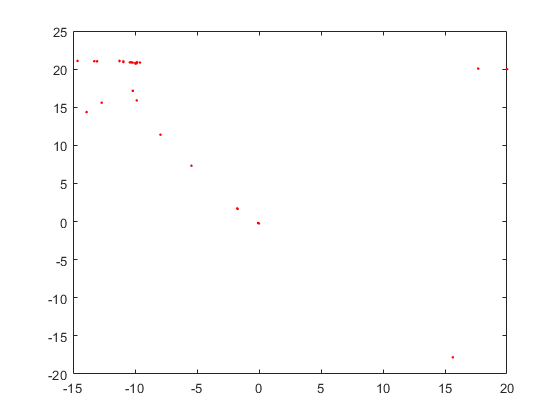

hold off

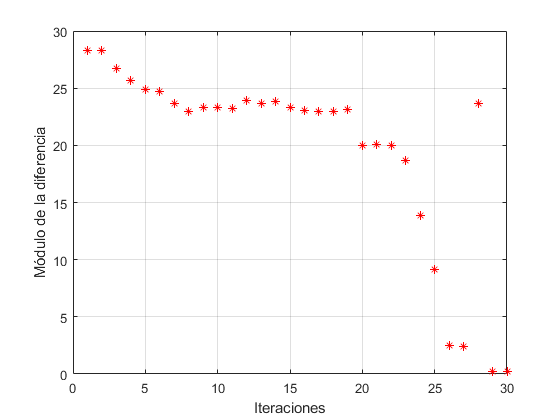

plot(1:length(mod_r_c),mod_r_c,"*r")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 0.2286

c0

c0 =    -0.0332
   -0.2261


u

u =           18           1           2           3          28           2           1        3003           2          13        3002           5        3002        3003        3002        3002           5        3002           3           8          11           1           3        3002           8           9          85           1           6           1


num_iteraciones=sum(u) %número de iteraciones

num_iteraciones = 24234